Generate Monte Carlo simulated escape times for three different affinity functions

addpath('1d');
% Set to 0 to not automatically regenerate MC statistics when running script
generate_data = 0;
if generate_data
S = load('1d/systems.mat');
eps_range = linspace(0.15, 0.2, 6);
dtmax = 100000;
% Results in paper used 5000 trials, can be lowered to run faster
trials = 10;
out1 = well_escape_statistics(S.system1, eps_range, dtmax, trials);
out2 = well_escape_statistics(S.system2, eps_range, dtmax, trials);
out3 = well_escape_statistics(S.system3, eps_range, dtmax, trials);
save('1dstats3.mat','out1','out2','out3');
end

S = load('1d/systems.mat');
load("1dstats3.mat");

Compute the deterministic and quasipotential barriers for each of the affinity functions. Observe that the quasipotential barrier is significantly lower than the deterministic barrier in all cases.

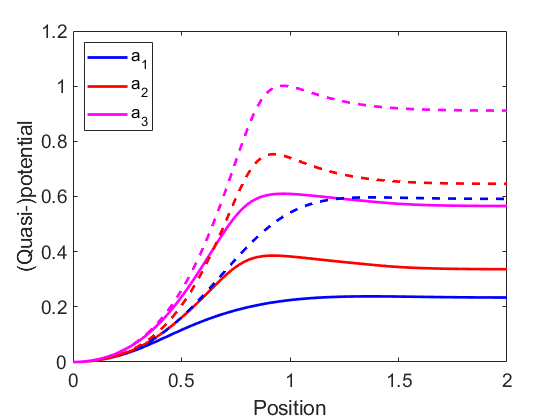

x = linspace(0, 2);
cd('1d');
U1 = deterministic_U(S.system1, x);
U2 = deterministic_U(S.system2, x);
U3 = deterministic_U(S.system3, x);

W1 = compute_W(S.system1, x);
S1 = max(W1);
W2 = compute_W(S.system2, x);
S2 = max(W2);
W3 = compute_W(S.system3, x);
S3 = max(W3);
cd ('../');

% Plot the deterministic and quasipotential barriers
plot(x, W1, 'b', x, W2, 'r', x, W3, 'm', x, U1, 'b--', x, U2, 'r--', x, U3, 'm--','LineWidth',2);
xlabel('Position');
ylabel('(Quasi-)potential')
legend('a_1','a_2','a_3',"Location","northwest");
set(gca,'FontSize',14);
saveas(gca,'figures/1a.png');

Compare slopes of the Monte Carlo statistics to the quasipotential barrier

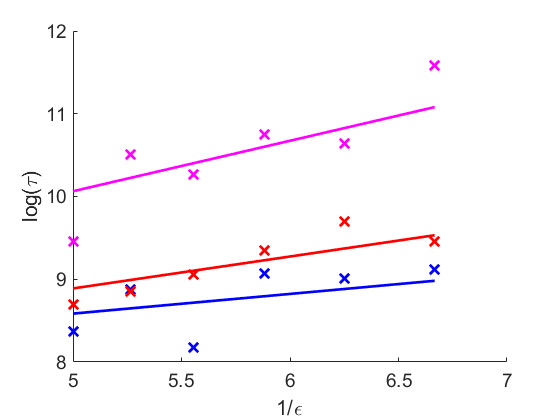

scatter(1./out1.eps_range, log(out1.mean_times), 100, 'bx', 'LineWidth', 2);
hold on;
scatter(1./out2.eps_range, log(out2.mean_times), 100, 'rx', 'LineWidth', 2);
scatter(1./out3.eps_range, log(out3.mean_times), 100, 'mx', 'LineWidth', 2);
% do linear fits
fit_x = 1./out1.eps_range; fit_y = log(out1.mean_times);
%p1 = polyfit(fit_x, fit_y, 1);
intercept1 = mean(fit_y) - S1*mean(fit_x);
fit_x = 1./out2.eps_range; fit_y = log(out2.mean_times);
%p2 = polyfit(fit_x, fit_y, 1);
intercept2 = mean(fit_y) - S2*mean(fit_x);
fit_x = 1./out3.eps_range; fit_y = log(out3.mean_times);
%p3 = polyfit(fit_x, fit_y, 1);
intercept3 = mean(fit_y) - S3*mean(fit_x);

% TODO: compute these offsets properly and automatically
plot(fit_x, S1*fit_x + intercept1, 'b', fit_x, S2*fit_x+ intercept2, 'r', fit_x, S3*fit_x + intercept3,'m', 'LineWidth',2)
hold off;
xlabel('1/\epsilon'); ylabel('log(\tau)')
set(gca, "FontSize", 14)
saveas(gca, 'figures/1b.png')